Reading WAV file and get a 10 seconds track

path_to_file = '/home/erich/src/proyecto_pds/codigo/matlab/toolbox/data_WAV/Systematic_Scale-C-Major_Meinard_fast.wav'

path_to_file = '/home/erich/src/proyecto_pds/codigo/matlab/toolbox/data_WAV/Systematic_Scale-C-Major_Meinard_fast.wav'

[f_audio, side_info] = wav_to_audio('', '', path_to_file);
%s = f_audio(100000:300000);
s = f_audio;

Plot audio signal

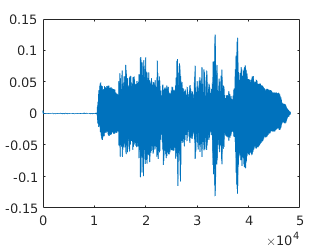

plot(s);

Getting a spectrogram

    AlignVertexCenters: {[on]  [off]}
            BusyAction: {'queue'  'cancel'}
         ButtonDownFcn: {}
              Children: {}
              Clipping: {[on]  [off]}
                 Color: {1×0 cell}
           ContextMenu: {}
             CreateFcn: {}
             DeleteFcn: {}
           DisplayName: {}
      HandleVisibility: {'on'  'callback'  'off'}
               HitTest: {[on]  [off]}
         Interruptible: {[on]  [off]}
              LineJoin: {'chamfer'  'miter'  'round'}
             LineStyle: {'-'  '--'  ':'  '-.'  'none'}
             LineWidth: {}
                Marker: {'+'  'o'  '*'  '.'  'x'  'square'  'diamond'  'v'  '^'  '>'  '<'  'pentagram'  'hexagram'  '|'  '_'  'none'}
       MarkerEdgeColor: {'auto'  'none'}
       MarkerFaceColor: {'auto'  'none'}
         MarkerIndices: {}
            MarkerSize: {}
                Parent: {}
         PickableParts: {'visible'  'none'  'all'}
              Selected: {[on]  [off]}
    SelectionHighlight: {[on]  [off

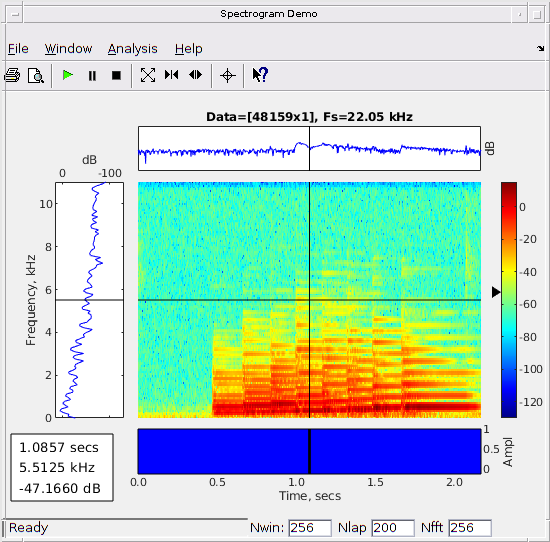

specgram_signal(s, 22050);

Inspecting filters with freqz

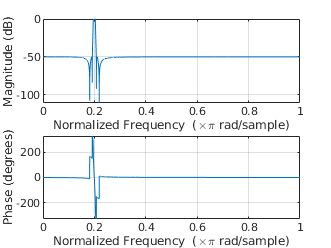

load MIDI_FB_ellip_pitch_60_96_22050_Q25.mat
midi_index = 69;  % For A4
b = h(midi_index).b;
a = h(midi_index).a;

freqz(b, a, 22050);

Getting pitch from track

Computing subbands and STMSP for all pitches: (21-108):  108


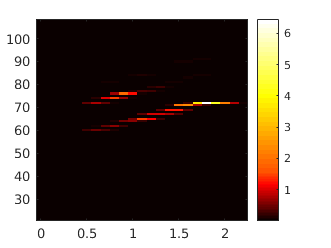

paramPitch.winLenSTMSP = 4410;
paramPitch.visualize = 1;

[f_pitch, side_info] = audio_to_pitch(s, paramPitch, side_info);

Compute chroma from pitch

HOLAAAAA


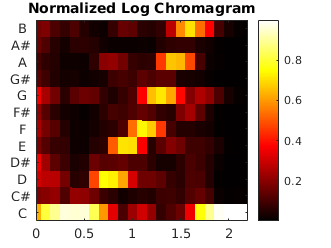

paramCP.applyLogCompr = 1;
paramCP.visualize = 1;
paramCP.inputFeatureRate = side_info.pitch.featureRate;
[f_CP, side_info] = pitch_to_chroma(f_pitch, paramCP, side_info);